# IRB140 Workspace exercise

Javier Cabrera

Link: [https://drive.matlab.com/sharing/0a86102f-bff8-487a-becf-cec9e27c6380](https://drive.matlab.com/sharing/0a86102f-bff8-487a-becf-cec9e27c6380)

Make the same exercise for the irb140 manipulator and plot the working area as shown in the figure

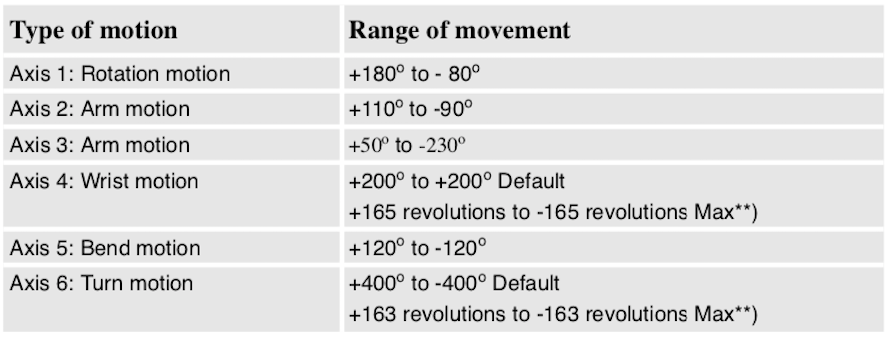

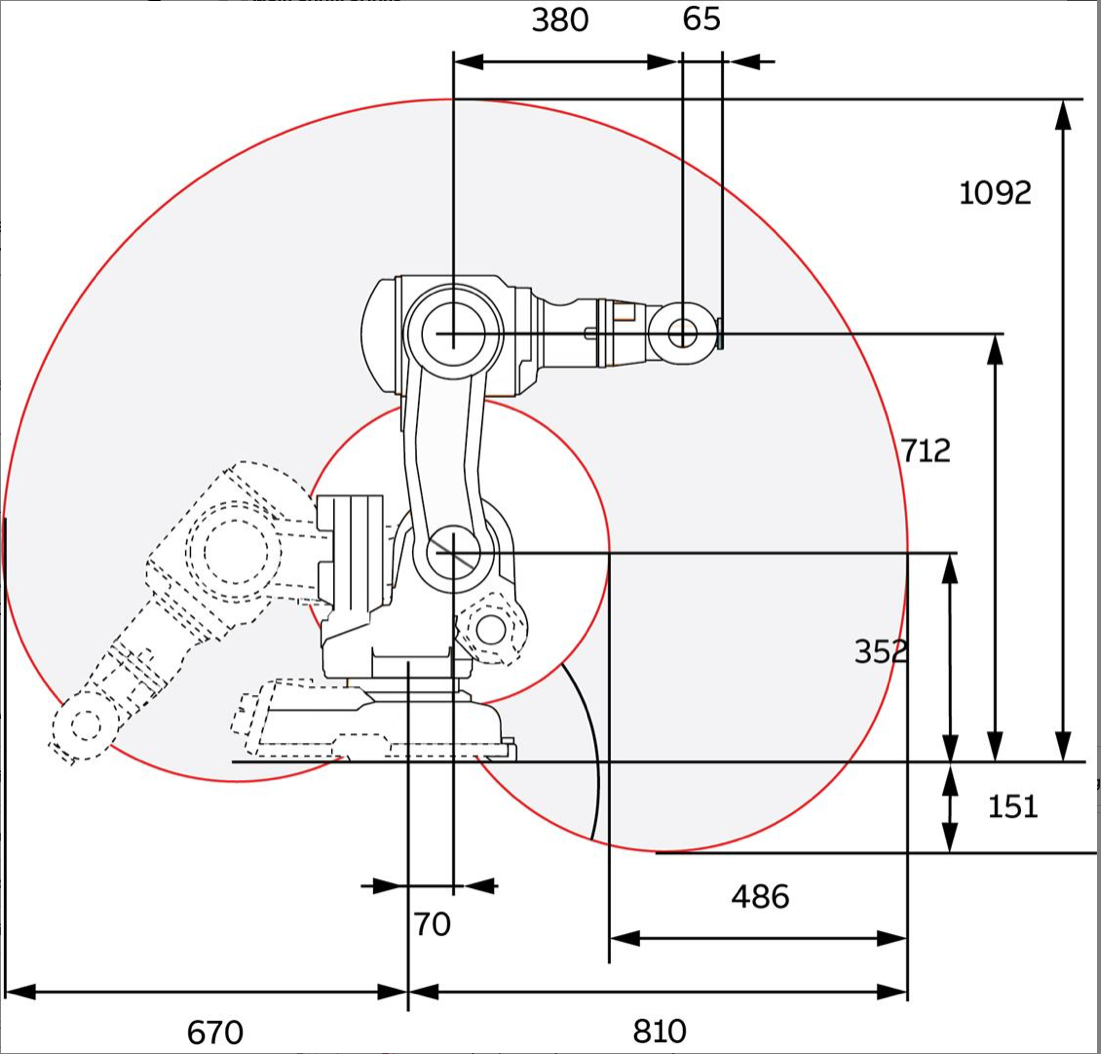

## Invoque IRB140 

clear;
close all;
mdl_irb140;

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Calculate the limits

degree_limits = [NaN NaN;-180 20; -50 230] % Based on table ranges and having into account qr start ranges

degree_limits =    NaN   NaN
  -180    20
   -50   230


rad_limits = deg2rad(degree_limits)

rad_limits =        NaN       NaN
   -3.1416    0.3491
   -0.8727    4.0143



for x = 2:3 % We only need the 2nd and 3rd axis limits
    irb140.links(x).qlim = rad_limits(x,:);
end

## Initial approach: Trailing workspace while rotating both axes at same time

### Plot the IRB initial position

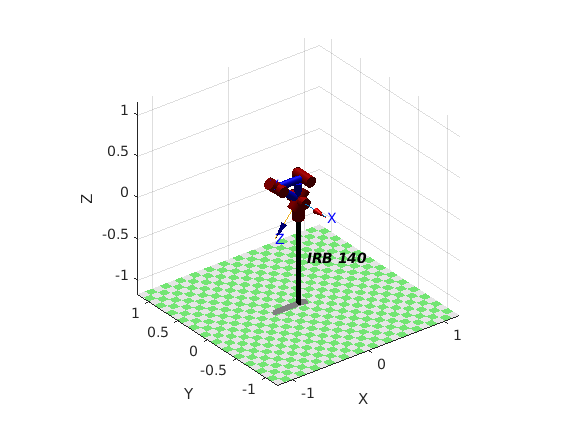

initial_position = [qr(1) rad_limits(2,1) rad_limits(3,1) qr(4:6)];
irb140.plot(initial_position)

### Build the movement matrix

iterations = 200;

q1 = zeros(iterations,1) + qr(1);
q2 = linspace(rad_limits(2,1),rad_limits(2,2),iterations)';
q3 = linspace(rad_limits(3,1),rad_limits(3,2),iterations)';
q4_6 = zeros(iterations,3) + qr(4:6);

Q = [q1 q2 q3 q4_6]

Q =          0   -3.1416   -0.8727         0    1.5708   -1.5708
         0   -3.1241   -0.8481         0    1.5708   -1.5708
         0   -3.1065   -0.8235         0    1.5708   -1.5708
         0   -3.0890   -0.7990         0    1.5708   -1.5708
         0   -3.0714   -0.7744         0    1.5708   -1.5708
         0   -3.0539   -0.7499         0    1.5708   -1.5708
         0   -3.0363   -0.7253         0    1.5708   -1.5708
         0   -3.0188   -0.7008         0    1.5708   -1.5708
         0   -3.0013   -0.6762         0    1.5708   -1.5708
         0   -2.9837   -0.6516         0    1.5708   -1.5708


### Plot the movement

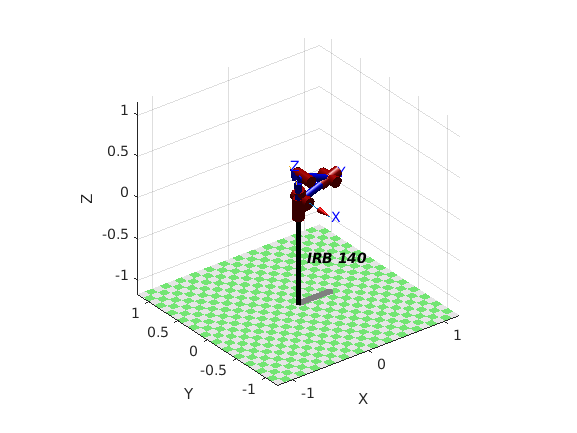

irb140.plot(Q,'trail','--','jaxes','zoom',2)

### Plot the trail

T = irb140.fkine(Q);
ft = [T.t]

ft =    -0.6700   -0.6699   -0.6695   -0.6690   -0.6682   -0.6672   -0.6659   -0.6644   -0.6627   -0.6608   -0.6586   -0.6563   -0.6537   -0.6508   -0.6478   -0.6445   -0.6410   -0.6373   -0.6334   -0.6293   -0.6249   -0.6204   -0.6156   -0.6106   -0.6054   -0.6000   -0.5944   -0.5885   -0.5825   -0.5763   -0.5699   -0.5633   -0.5565   -0.5494   -0.5423   -0.5349   -0.5273   -0.5195   -0.5116   -0.5035   -0.4952   -0.4867   -0.4781   -0.4693   -0.4603   -0.4512   -0.4419   -0.4324   -0.4228   -0.4131
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

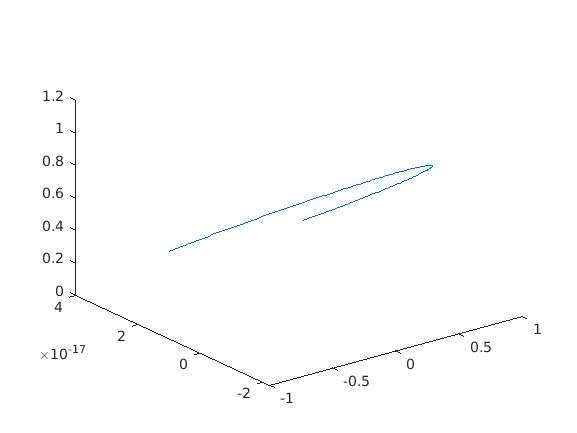

clf
figure
plot3(ft(1,:),ft(2,:), ft(3,:))

%view(0,0);

The result is very similar to the objective, but it isn't precise. This is because, excluding the rotation edges of q2, the other points could have q3 in its maximum length by having the arm straight.

## Second approach: Trailing full rotation of q3 at limits of q2

The workspace will be calculated in 3 parts, being the 2 first ones the edges of rotation of q2 having the full rotation of q3 and the third being q3 fixed in a straight position and having q2 rotate.

### Part 1 - With q2 fixed at slowest angle

#### Plot the IRB initial position

initial_position = [qr(1) rad_limits(2,1) rad_limits(3,1) qr(4:6)];
figure
irb140.plot(initial_position);

#### Build the movement matrix

iterations = 200;

q1 = zeros(iterations,1) + qr(1);
q2 = zeros(iterations,1) + (rad_limits(2,1));
q3 = linspace(rad_limits(3,1),rad_limits(3,2),iterations)';
q4_6 = zeros(iterations,3) + qr(4:6);

Q = [q1 q2 q3 q4_6]

Q =          0   -3.1416   -0.8727         0    1.5708   -1.5708
         0   -3.1416   -0.8481         0    1.5708   -1.5708
         0   -3.1416   -0.8235         0    1.5708   -1.5708
         0   -3.1416   -0.7990         0    1.5708   -1.5708
         0   -3.1416   -0.7744         0    1.5708   -1.5708
         0   -3.1416   -0.7499         0    1.5708   -1.5708
         0   -3.1416   -0.7253         0    1.5708   -1.5708
         0   -3.1416   -0.7008         0    1.5708   -1.5708
         0   -3.1416   -0.6762         0    1.5708   -1.5708
         0   -3.1416   -0.6516         0    1.5708   -1.5708


#### Plot the trail 

T = irb140.fkine(Q);
ft1 = [T.t]

ft1 =     0.0011   -0.0050   -0.0112   -0.0177   -0.0243   -0.0310   -0.0379   -0.0450   -0.0522   -0.0595   -0.0670   -0.0746   -0.0824   -0.0903   -0.0983   -0.1064   -0.1146   -0.1229   -0.1314   -0.1399   -0.1485   -0.1572   -0.1660   -0.1749   -0.1838   -0.1928   -0.2018   -0.2109   -0.2201   -0.2293   -0.2385   -0.2478   -0.2570   -0.2664   -0.2757   -0.2850   -0.2943   -0.3037   -0.3130   -0.3223   -0.3316   -0.3408   -0.3501   -0.3593   -0.3684   -0.3775   -0.3866   -0.3956   -0.4045   -0.4134
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

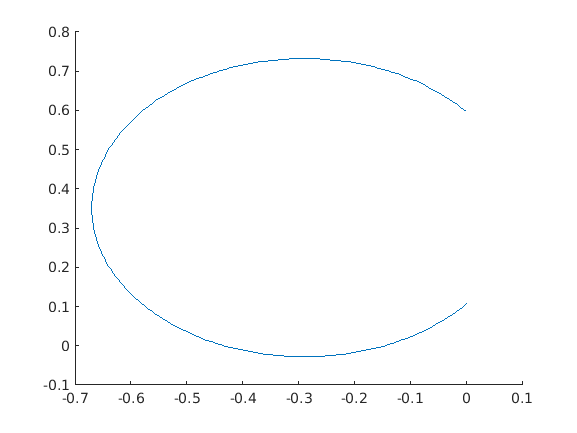

figure
plot3(ft1(1,:),ft1(2,:), ft1(3,:))
view(0,0);

### Part 2 - With q2 fixed at slowest angle

#### Plot the IRB initial position

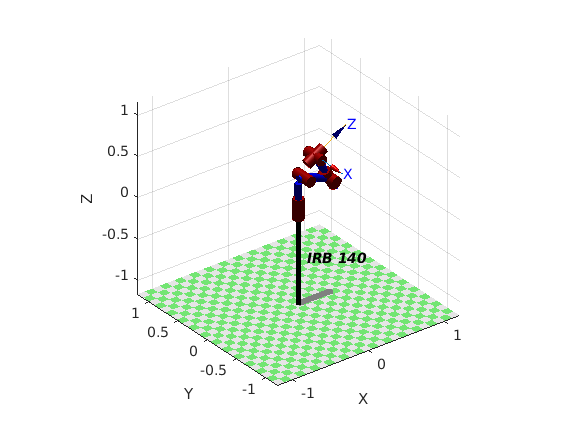

initial_position = [qr(1) rad_limits(2,2) rad_limits(3,1) qr(4:6)];
figure;
irb140.plot(initial_position);

#### Build the movement matrix

iterations = 200;

q1 = zeros(iterations,1) + qr(1);
q2 = zeros(iterations,1) + (rad_limits(2,2));
q3 = linspace(rad_limits(3,1),rad_limits(3,2),iterations)';
q4_6 = zeros(iterations,3) + qr(4:6);

Q = [q1 q2 q3 q4_6]

Q =          0    0.3491   -0.8727         0    1.5708   -1.5708
         0    0.3491   -0.8481         0    1.5708   -1.5708
         0    0.3491   -0.8235         0    1.5708   -1.5708
         0    0.3491   -0.7990         0    1.5708   -1.5708
         0    0.3491   -0.7744         0    1.5708   -1.5708
         0    0.3491   -0.7499         0    1.5708   -1.5708
         0    0.3491   -0.7253         0    1.5708   -1.5708
         0    0.3491   -0.7008         0    1.5708   -1.5708
         0    0.3491   -0.6762         0    1.5708   -1.5708
         0    0.3491   -0.6516         0    1.5708   -1.5708


#### Plot the trail 

T = irb140.fkine(Q);
ft2 = [T.t]

ft2 =     0.2183    0.2264    0.2347    0.2430    0.2515    0.2600    0.2687    0.2774    0.2862    0.2951    0.3040    0.3130    0.3221    0.3312    0.3403    0.3495    0.3588    0.3680    0.3773    0.3866    0.3960    0.4053    0.4146    0.4239    0.4333    0.4426    0.4519    0.4611    0.4703    0.4795    0.4887    0.4978    0.5068    0.5158    0.5247    0.5335    0.5423    0.5510    0.5596    0.5681    0.5765    0.5849    0.5931    0.6012    0.6091    0.6170    0.6247    0.6323    0.6398    0.6471
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

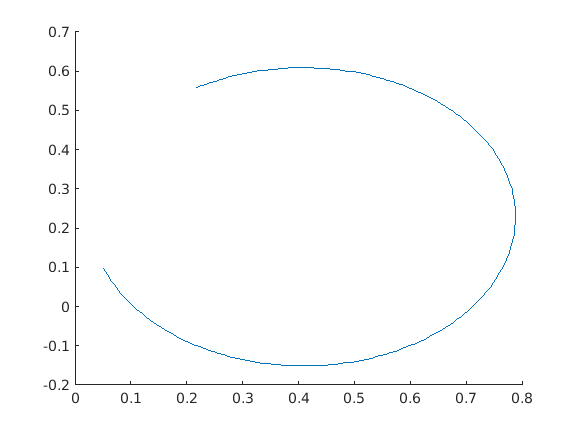

figure
plot3(ft2(1,:),ft2(2,:), ft2(3,:))
view(0,0);

### Part 3 - With q3 fixed at straight angle

#### Plot the IRB initial position

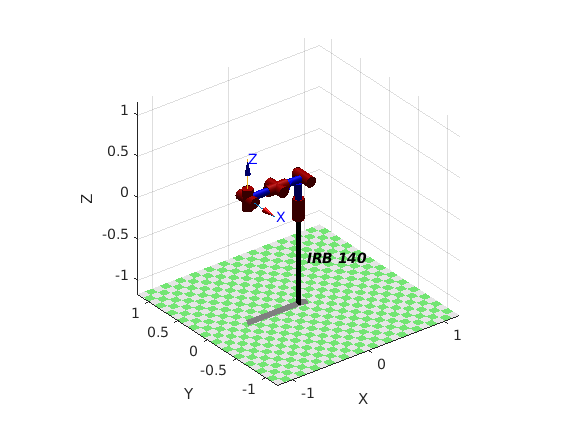

initial_position = [qr(1) rad_limits(2,1) qr(3:6)];
figure
irb140.plot(initial_position);

#### Build the movement matrix

iterations = 200;

q1 = zeros(iterations,1) + qr(1);
q2 = linspace(rad_limits(2,1),rad_limits(2,2),iterations)';
q3_6 = zeros(iterations,4) + qr(3:6);

Q = [q1 q2 q3_6]

Q =          0   -3.1416    1.5708         0    1.5708   -1.5708
         0   -3.1241    1.5708         0    1.5708   -1.5708
         0   -3.1065    1.5708         0    1.5708   -1.5708
         0   -3.0890    1.5708         0    1.5708   -1.5708
         0   -3.0714    1.5708         0    1.5708   -1.5708
         0   -3.0539    1.5708         0    1.5708   -1.5708
         0   -3.0363    1.5708         0    1.5708   -1.5708
         0   -3.0188    1.5708         0    1.5708   -1.5708
         0   -3.0013    1.5708         0    1.5708   -1.5708
         0   -2.9837    1.5708         0    1.5708   -1.5708


#### Plot the trail 

T = irb140.fkine(Q);
ft3 = [T.t]

ft3 =    -0.6700   -0.6699   -0.6695   -0.6690   -0.6682   -0.6672   -0.6659   -0.6644   -0.6627   -0.6608   -0.6586   -0.6563   -0.6537   -0.6508   -0.6478   -0.6445   -0.6410   -0.6373   -0.6334   -0.6293   -0.6249   -0.6204   -0.6156   -0.6106   -0.6054   -0.6000   -0.5944   -0.5885   -0.5825   -0.5763   -0.5699   -0.5633   -0.5565   -0.5494   -0.5423   -0.5349   -0.5273   -0.5195   -0.5116   -0.5035   -0.4952   -0.4867   -0.4781   -0.4693   -0.4603   -0.4512   -0.4419   -0.4324   -0.4228   -0.4131
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   

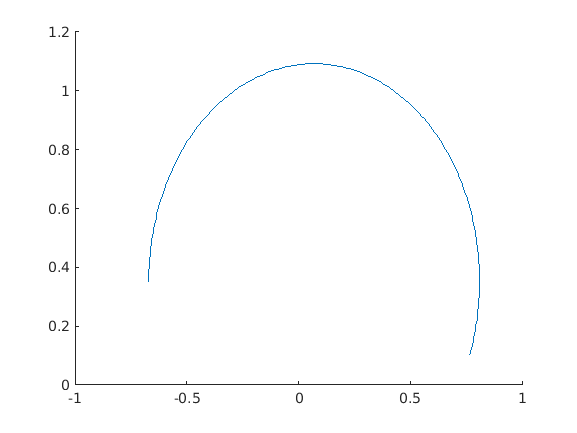

figure
plot3(ft3(1,:),ft3(2,:), ft3(3,:))
view(0,0);

### Plot the combined trail

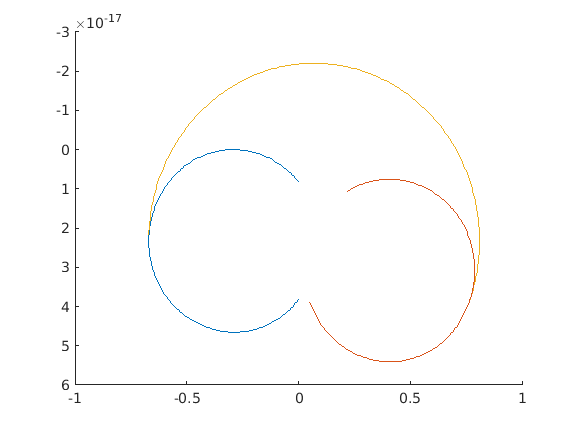

figure
hold on
plot3(ft1(1,:),ft1(2,:), ft1(3,:))
plot3(ft2(1,:),ft2(2,:), ft2(3,:))
plot3(ft3(1,:),ft3(2,:), ft3(3,:))
set(gca, 'YDir','reverse') % No sé porque se imprime del revés el workspace, cuando en el resto de plots se ve perfectamente. Esta linea es un workaround. 
hold off